# Material Addition 1-Dimension

Just starting from scratch (though I started earlier with 2D).  This is a 1-D transient problem with heat source and material addition (hopefully both Quiet Activation and On-off). 

Solving 1D PDE uses `pdepe `function and does not require MATLAB PDE toolbox. 

From Matlab documentation ([https://www.mathworks.com/help/matlab/ref/pdepe.html](https://www.mathworks.com/help/matlab/ref/pdepe.html))


$$c(x,t,u,\frac{\partial u}{\partial x}) \frac{\partial u}{\partial t} = x^{-m} \frac{\partial }{\partial x}(x^m f(x,t,u,\frac{\partial u}{\partial x}) + s(x,t,u,\frac{\partial u}{\partial x})$$
 

is the form of the equation. 

clear; 
close all;

The generic heat equation is given as 


$$\rho c_p \frac{\partial T}{\partial t} = \frac{\partial }{\partial x}(k \frac{\partial T}{\partial x}) + Q$$
     

For material addition and moving heat source - $\rho$, $c_p$, $k$, and $Q$ depend on $x$ and $t$. 

Problem Setup

Consider a 1D rod with heat source moving from left to right at a constant velocity $v_s$. Consider that the heat source has (1D) radius $r_l$. 

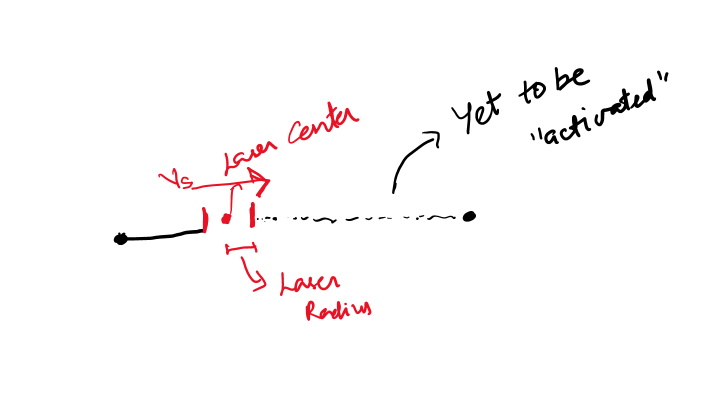

L_rod = 1; % mm?
T_a = 300; %Kelving Ambient Temperature

x = linspace(0,L_rod,100);
t = linspace(0,1,25);

## Process Parameters

laser_power = 150; %Watts
scan_speed = 0.8; %mm/s %Set it appropriately to match the length vs time scale
laser_radius = 0.1; %mm?
laser_absorptivity = 0.4;

process_params = struct('scan_speed',scan_speed, 'laser_power',laser_power, ...
    'laser_radius', laser_radius,'laser_absorptivity',laser_absorptivity);  

heat_source_func = @(x,t) Q_moving_1D(x,t,process_params,L_rod);

## Material Properties

k_300K = 1; % thermal conductivity of copper, W/(m-K)
rho_300K = 0.00844; % density of copper, kg/m^3
c_p_300K = 410; % specific heat of copper, J/(kg-K)

Quiet Activation Strategy

- Assume an element is "activated" if it is within the radius $r_l$ of the heat source and stays activated (obviously). 

Thus, tracking the center of the heat source will provide all the necessary details for heat source and material properties. 

density = @(x,t) rho(x,t,rho_300K,process_params,L_rod);
specific_heat = @(x,t) c_p(x,t,c_p_300K,process_params,L_rod);
conductivity = @(x,t) k(x,t,k_300K,process_params,L_rod);
material_prop_funcs = {density,specific_heat,conductivity};

## Solving

Assuming insulated at both ends. 

Initially everything is at room temperature.  

heat_pde_func = @(x,t,u,dudx) heat_pde_coeffs(x,t,u,dudx,material_prop_funcs,heat_source_func);
heat_ic_func = @(x) heat_initial_cond(x,T_a);
heat_bc_func = @(xl,ul,xr,ur,t) heat_boundary_cond(xl,ul,xr,ur,t);

Now actually solving, 

m = 0; %Indicates a rectangle: check documentation
tic
sol = pdepe(m,heat_pde_func,heat_ic_func,heat_bc_func,x,t);
toc

Elapsed time is 50.124879 seconds.


## Analyzing Solution

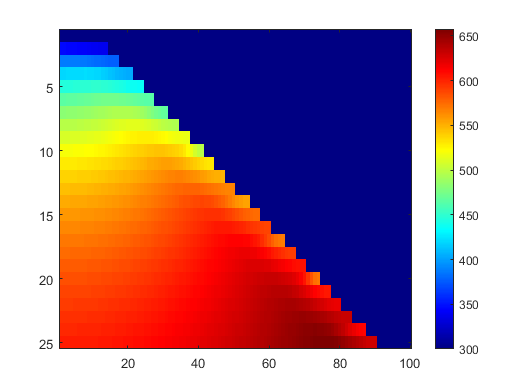

imagesc(sol)
colormap jet
colorbar

max(sol(:))

ans = 657.7850